clear all
close all

addpath('../dsfo_toolbox/');

Solve the Canonical Correlation Analysis (CCA) problem, given by:


$$\text{arg}\max_{X,W}\mathbb{E}[\text{trace}(X^T\mathbf{y}(t)\mathbf{v}^T(t)W]\\
\text{s.t. } \mathbb{E}[X^T\mathbf{y}\mathbf{y}^T(t)X]=I, \mathbb{E}[W^T\mathbf{v}\mathbf{v}^T(t)W]=I,$$


in a distributed context using the Distributed Signal Fusion Optimization (DSFO) framework.

Let us first define the network. We take a randomly connected network with 10 nodes and 5 channels per node.

nbnodes=10;
nbsensors_vec=5*ones(nbnodes,1);
nbsensors=sum(nbsensors_vec);
adj=randi(2,nbnodes,nbnodes)-1;
graph_adj=triu(adj,1)+tril(adj',-1);
non_connected=find(all(graph_adj==0));
% If there are non-connected nodes, connect them to every other node.
if(non_connected)
    graph_adj(:,non_connected)=1;
    graph_adj(non_connected,:)=1;
end

Since we have $2$ variables, namely $X$ and $W$, we write:

nbvariables=2;

Next, we create the data using 

found at the end of this file. The number of time samples of the signals is 10000 and we choose the number of filters to be equal to 2, i.e., $X$ and $W$ have 2 columns each.

nbsamples=10000;
[Y,V]=create_data(nbsensors_vec,nbnodes,nbsamples);
Q=2;

The data are stored in 4 different cells, 

- One for the (stochastic) signals. In this example, the cell contains two elements, the signals $\mathbf{y}$ and $\mathbf{v}$. 

Y_cell{1}=Y;

- One for deterministic constant matrices. In this example, we do not have any.

B_cell={};

- One for quadratic terms. In this example, we do not have any.

Gamma_cell={};

- The final one for global constraint parameters, i.e., those that are not filtered using $X$. In this case, we do not have any.

Glob_Const_cell={};

We repeat the same for the data regarding the variable $W$:

V_cell{1}=V;

We then create structures for the data, problem parameters and stopping criteria, and since we have a set of two variables $(X,W)$, we create a data structure for each:

Then, `data` is a cell, containing the structures for the data corresponding to the different variables.

data_X=struct;
data_X.Y_cell=Y_cell;
data_X.B_cell={};
data_X.Gamma_cell={};
data_X.Glob_Const_cell={};

data_W=struct;
data_W.Y_cell=V_cell;
data_W.B_cell={};
data_W.Gamma_cell={};
data_W.Glob_Const_cell={};

data=cell(nbvariables,1);
data{1}=data_X;
data{2}=data_W;

prob_params=struct;
prob_params.nbsensors=nbsensors;
prob_params.Q=Q;
prob_params.nbnodes=nbnodes;
prob_params.nbsensors_vec=nbsensors_vec;
prob_params.nbsamples=nbsamples;
prob_params.graph_adj=graph_adj;
prob_params.nbvariables=nbvariables;

We fix the number of iterations the DSFO algorithm will perform to 1000.

conv=struct;
conv.nbiter=1000;

We choose a randomly selected updating order for the distributed implementation:

prob_params.update_path=randperm(nbnodes);
prob_params.update_path

ans =      2     8     1     3     5     6     9     7    10     4


Then, an optimal set of filters $(X^*,W^*)$ solving the CCA problem is estimated using the centralized algorithm: 

Note that any simultaneous sign change on the columns of both $X^*$ and $W^*$ is also a valid solution.

[X_star,f_star]=cca_solver(prob_params,data);
prob_params.X_star=X_star;
% Compute the distance to X^* if "true". 
prob_params.compare_opt=true;
% Show a dynamic plot if "true".
prob_params.plot_dynamic=false;

The distributed implementation is then called using the function 

 which takes as parameters the data, problem parameter and stopping criteria structures along with the functions 

which evaluates the CCA objective given a certain pair $(X,W)$, solves the centralized CCA problem and resolves the uniqueness ambiguity of the CCA, respectively.

[X_est,norm_diff,norm_err,f_seq]=dsfo_multivar(prob_params,data,...
        @cca_solver,conv,@cca_select_sol,@cca_eval);

Let us plot the normalized error $\epsilon$ given by:

$\epsilon\left((X^i,W^i)\right)=\frac{\Big|\Big|[X^i,W^i]-[X^*,W^*]\Big||_F^2}{\Big|\Big|[X^*,W^*]\Big||_F^2}$,

which is stored in

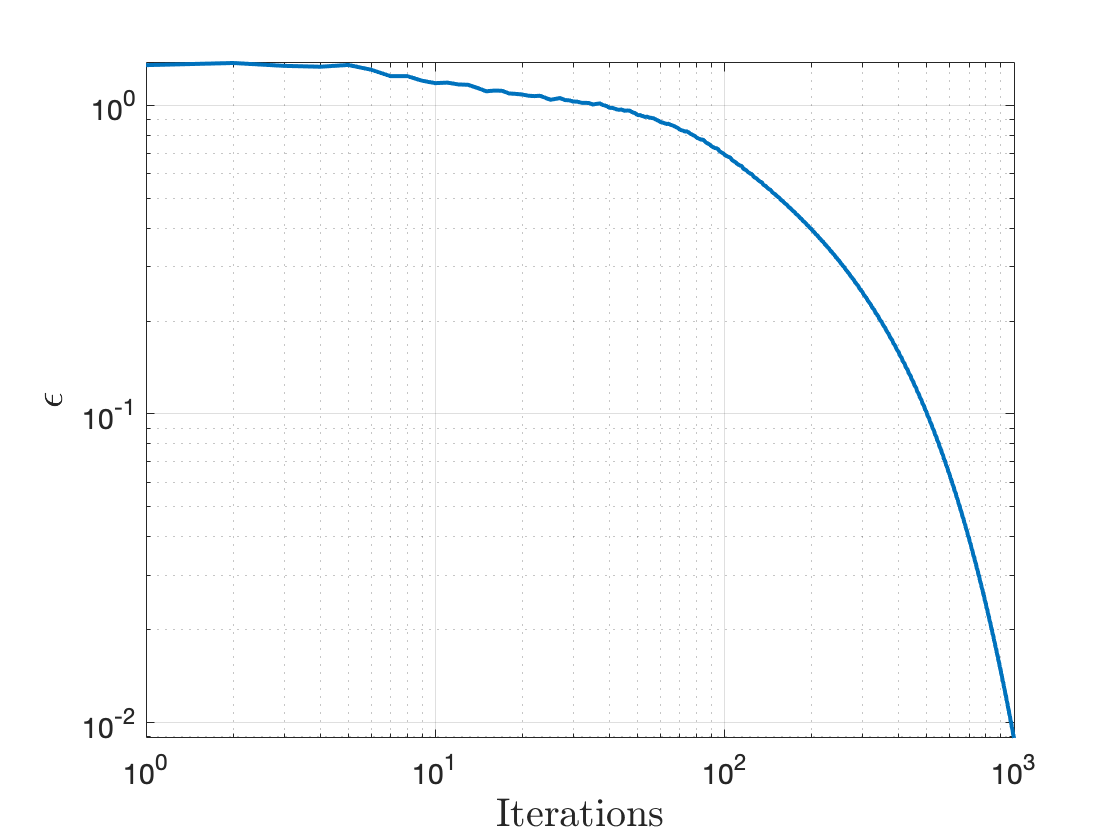

loglog([1:1000],norm_err,'LineWidth',2)
ax=gca;
ax.FontSize=14;
xlim([1,inf])
xlabel('Iterations','Interpreter','latex','Fontsize',20)
ylabel('$\epsilon$','Interpreter','latex','Fontsize',20)
grid on

Function used to create the signals $\mathbf{y}$ and $\mathbf{v}$.

function [Y,V]=create_data(nbsensors_vec,nbnodes,nbsamples)
    
    noisepower=0.1;
    signalvar=0.5;
    nbsources=10;
    offset=0.5;
    lags=3;

    rng('shuffle');
    D=randn(nbsources,nbsamples+lags);
    D=sqrt(signalvar)./(sqrt(var(D,0,2))).*(D-mean(D,2)*ones(1,nbsamples+lags));

    for k=1:nbnodes
        A{k}=rand(nbsensors_vec(k),nbsources)-offset;
        noise{k}=randn(nbsensors_vec(k),nbsamples+lags); 
        noise{k}=sqrt(noisepower)./sqrt(var(noise{k},0,2)).*(noise{k}...
            -mean(noise{k},2)*ones(1,nbsamples+lags)); 
    end

    column_blk=0;

    signal_cell=cell(nbnodes,1);
    Y_cell=cell(nbnodes,1);
    V_cell=cell(nbnodes,1);
    
    for k=1:nbnodes
        signal_cell{k}=A{k}*D+noise{k};
        Y_cell{k}=signal_cell{k}(:,1:nbsamples);
        V_cell{k}=signal_cell{k}(:,lags+1:end);

        Y(column_blk+1:column_blk+nbsensors_vec(k),1:nbsamples)=Y_cell{k};
        V(column_blk+1:column_blk+nbsensors_vec(k),1:nbsamples)=V_cell{k};
        column_blk=column_blk+nbsensors_vec(k);
    end

end